fk=1000 %采样频率

fk = 1000

N=10301 %采样个数

N = 10301

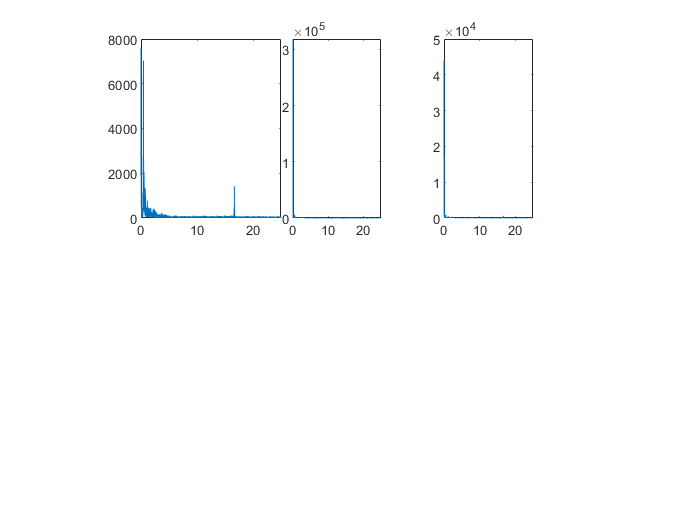

n=-N/2:N/2-1;
f=n*fk/N;
t=n/fk;
for i=1:7
    y(:,i)=A3(:,i);
    fft_y(:,i)=fft(y(:,i));
    fftshift_y(:,i)=fftshift(fft_y(:,i));
end
f=linspace(-25,25,10301);
subplot(2,11,[2,4])
y=A3(:,1);
fft_y=fft(y);
fftshift_y=fftshift(fft_y);
f=linspace(-25,25,10301);
plot(f,abs(fftshift_y));%滤波前频谱分析
xlim([0,25]);
subplot(2,11,[5,6])
y=A3(:,2);
fft_y=fft(y);
fftshift_y=fftshift(fft_y);
f=linspace(-25,25,10301);
plot(f,abs(fftshift_y));
xlim([0,25]);
subplot(2,11,[8,9])
y=A3(:,3);
fft_y=fft(y);
fftshift_y=fftshift(fft_y);
f=linspace(-25,25,10301);
plot(f,abs(fftshift_y));
xlim([0,25]);